Signal with multiple measurements

**Auditory Brainstem Response with EEG noise**

load ABR_rec.mat;

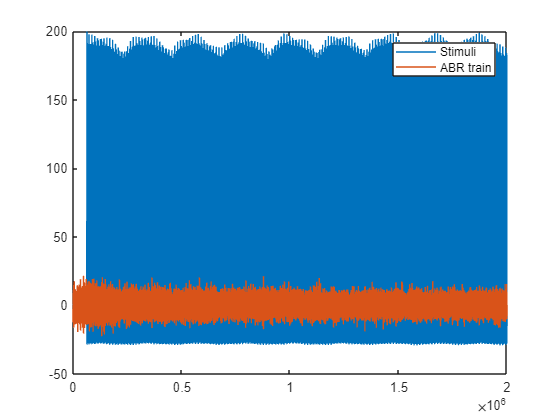

figure;
plot(ABR_rec);
legend('Stimuli','ABR train');

thresh = find(ABR_rec(:,1)>50);


j=1;
for i=1:length(thresh)-1
    if thresh(i+1)-thresh(i)>1
        stim_point(j,1)=thresh(i+1);
        j=j+1;
    end
end

j = 0;
for i=1:length(stim_point)
    j = j + 1;
    epochs(:,j) = ABR_rec((stim_point(i)-80:stim_point(i)+399),2);
end

ensmbl_avg = mean(epochs(:,(1:length(stim_point))),2);

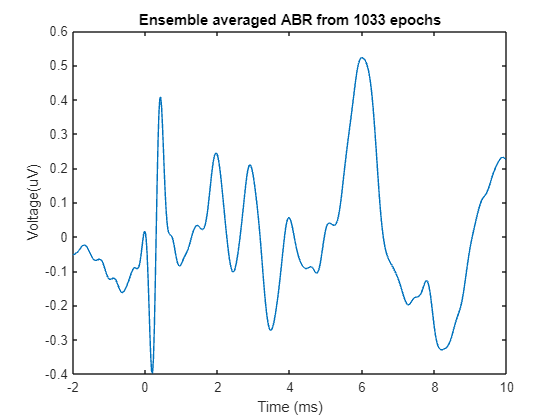

figure,
plot((-80:399)/40,ensmbl_avg);
xlabel('Time (ms)');
ylabel('Voltage(uV)');
title(['Ensemble averaged ABR from ' num2str(length(epochs)) ' epochs']);

N = size(epochs,1);
M = size(epochs,2);


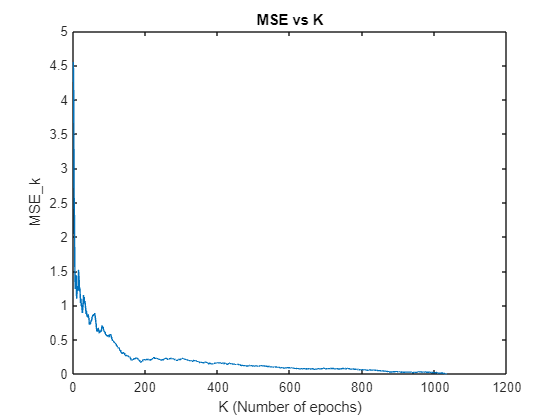

MSE_array = [];
for k = 1:1033
    MSE_k = MSE_for_ensemble(k,epochs,ensmbl_avg);
    MSE_array = [MSE_array, MSE_k];
end

plot(MSE_array);
xlabel("K (Number of epochs)");
ylabel("MSE\_k");
title("MSE vs K");

Signal with repetitive patterns

**Periodic ECG recording with AWGN**

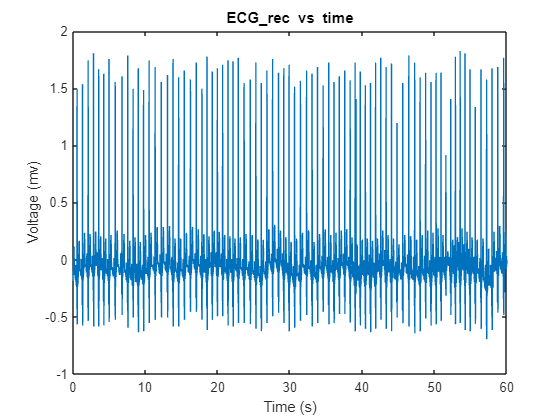

clear global;
clc;
load ("ECG_rec.mat");

fs = 128;
T = 1/fs;

num_points = size(ECG_rec,2);
time_axis = linspace(0, T * (num_points-1), num_points);

plot(time_axis,ECG_rec);
xlabel("Time (s)");
ylabel("Voltage (mv)");
title("ECG\_rec vs time");

By observing the plot, from time 0.2891s to 1.0078 s is selected as the template for the ECG.

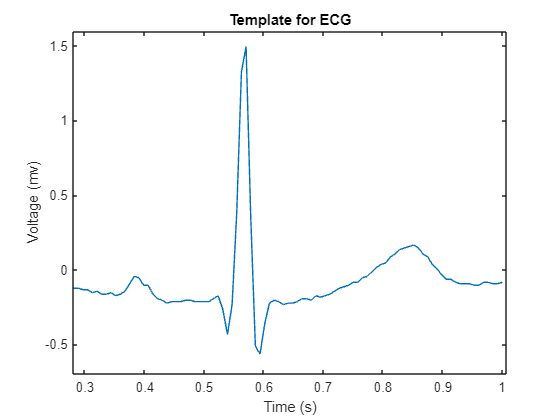

start_time = 0.2891;
end_time = 1.0078;

start_n = round(start_time / T);
end_n = round(end_time / T);

ECG_template = ECG_rec(start_n:end_n);

plot( time_axis(start_n:end_n),ECG_template);
xlabel("Time (s)");
ylabel("Voltage (mv)");
title("Template for ECG");
xlim([0.28 1.008])
ylim([-0.7 1.6]);

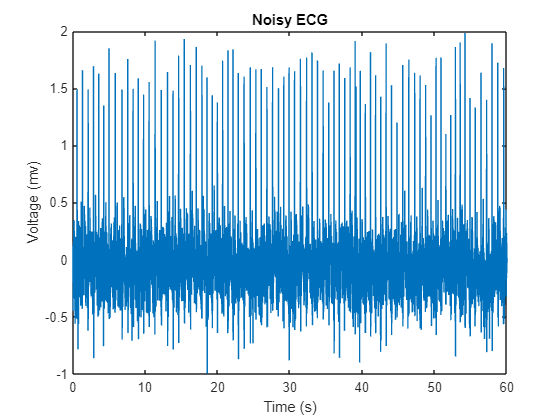

Snr = 5; %signal-noise ratio in decible
seed = 10;
nECG = awgn(ECG_rec,Snr,'measured',seed);

plot(time_axis,nECG);
xlabel("Time (s)");
ylabel("Voltage (mv)");
title("Noisy ECG");

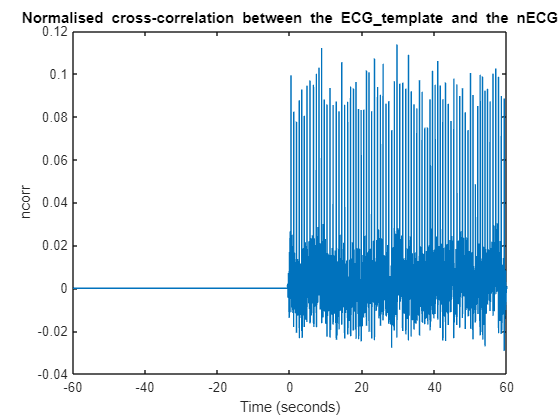

padding_size = length(nECG)-length(ECG_template);
ECG_template_padded = padarray(ECG_template, [0,padding_size],'post');
[c, lags] =  xcorr(nECG, ECG_template_padded, 'normalized');

plot(lags*T,c);
xlabel("Time (seconds)");
ylabel("ncorr");
title("Normalised cross-correlation between the ECG\_template and the nECG");

positive_lags = lags(lags>=0);
xcorr_for_positive_lags = c(lags>=0);

thresh_xcorr = find(xcorr_for_positive_lags>0.05);

j=1;
for i=1:length(thresh_xcorr)-1
    if thresh_xcorr(i+1)-thresh_xcorr(i)>1
        stim_point_ECG(j,1)=thresh_xcorr(i+1);
        j=j+1;
    end
end


j = 0;
for i=1:length(stim_point_ECG)
    j = j + 1;
    epochs_ECG(:,j) = nECG(stim_point_ECG(i):stim_point_ECG(i)+length(ECG_template)-1);
end

ensmbl_avg_ECG  = transpose(mean(epochs_ECG(:,(1:length(stim_point_ECG))),2));

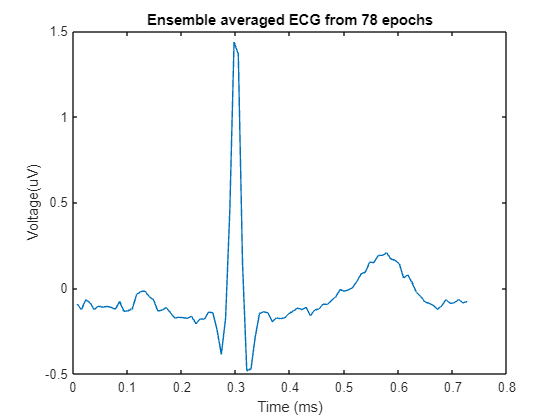


figure,
plot((1:length(ECG_template))*T,ensmbl_avg_ECG);
xlabel('Time (ms)');
ylabel('Voltage(uV)');
title(['Ensemble averaged ECG from ' num2str(size(epochs_ECG,2)) ' epochs']);

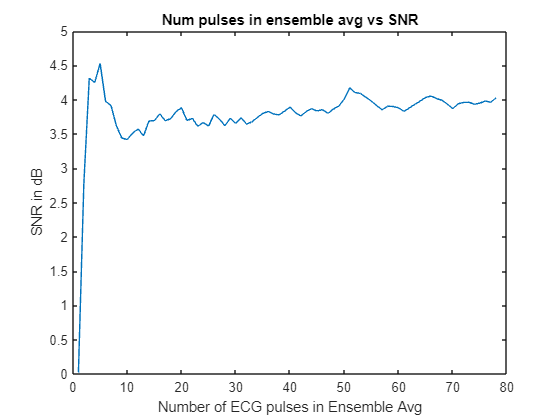

% SNR comparison
SNR_values = [];
num_pulses = [];

for number = 1:length(stim_point_ECG)
    ensmbl_avg_for_num_pulses  = transpose(mean(epochs_ECG(:,(1:number)),2));
    noise = ensmbl_avg_for_num_pulses - ECG_template;
    SNR_num_pulses = snr(ECG_template,noise);
    SNR_values = [SNR_values, SNR_num_pulses];
    num_pulses = [num_pulses, number];
end

plot(num_pulses,SNR_values);
xlabel("Number of ECG pulses in Ensemble Avg");
ylabel("SNR in dB");
title("Num pulses in ensemble avg vs SNR");

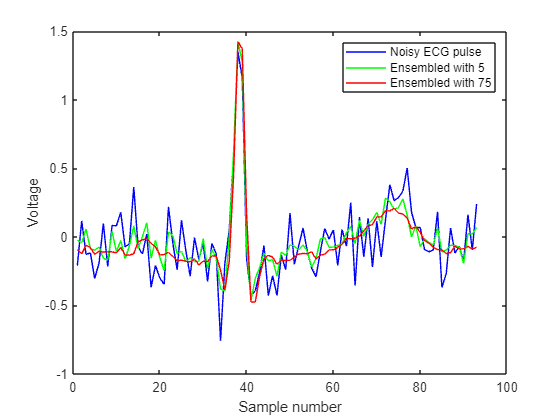

plot(epochs_ECG(:,5),'b');
hold on;
plot(transpose(mean(epochs_ECG(:,(1:5)),2)),'g');
hold on;
plot(transpose(mean(epochs_ECG(:,(1:75)),2)),'r');
hold off;
xlabel("Sample number");
ylabel("Voltage");
legend("Noisy ECG pulse", "Ensembled with 5", "Ensembled with 75");